% ProcessSensorLetterLivePXI.mlx
% Authors: Fabio Rizental Coutinho, Andre L. Stakowian, Marco J. Da Silva
% Matlab R2023A
% please refer to the paper "A fast and improved dual-PRT Doppler technique
% for industrial flow metering" for further details

% Open PXI file
clearvars;clc; %clear workspace
[filename,path,FilterIndex] = uigetfile('*.mat',   'Select PXI file to be open');
load([path filename]); fclose('all');
filename % print filename for verification

filename = '2021-11-04 17_16_34_,637_fromUVP_JL_130_18g.mat'

%crop data
acq.data=acq.data(acq.amostrasini:acq.amostrasfim,:);
%acq.data format: each line comprises of an ultrasound emission, i. e.
% acq.data(:,1) is the echoes returned at the first ultrasound emission,
% and so on, column data, are the RF data and are sampled at 50 MHz
% acq.data was acquired with a uniform Pulse Repetition Time (PRT),
% PRT=1/acq.prf (PRF : Pulse Repetition Frequency)
acq.c=1492;% m/s, set soundspeed measured for the measured data

% Measurement parameters

acq.fc=1e6*4; %transducer central frequency
res_espac= acq.c*acq.ciclos/(2*acq.fc); % spatial resolution or range gate or ChannelWidth (UVP)
Ns=2*res_espac*acq.fs/(acq.c); % Sample size that is equivalent to a range gate
dec=10;% spatial decimation, if dec=10 then RF sampling frequency(fs) is divided by 10 after complex demodulation
Nc=128; %number of ultrasonic emissions for estimating a spatial velocity profile 
ovt=1; ovs=1;
posfiltersize=1;%enable median filter to smooth velocity map (post processing)
p=0; %-1 disable filter, any other number specify the filter order
acq.m=2; % setup the PRT ratio, will drop emission according to the PRT ratio chosen
M=9;% setup the window size for outlier correction
ciclosmatched=acq.ciclos; % setup matched filter based on the number of cycles emitted by the ultrasound
% print some parameters for verification purposes
Ns % number of samples of a range gate 

Ns = 50

dec % RF decimation factor (used after IQ demodulation)

dec = 10

Nc % number of emissions used for estimation each velocity

Nc = 128

M % windows size of outlier correction algorithm

M = 9

## Complex demodulation or IQ-Demodulation


% Echoes aquired are not hardware IQ demodulated, thus demodulation should
% be done. Sampling frequency is not 4x transducer central frequency,
% therefore the demodulation should be done using hilbert followed by complex exponential
% multiplication
iq=hilbert(acq.data);% transform RF data(real) to complex data (assimetric frequency spectrum)
t=(0:1/acq.fs:size(iq,1)*(1/acq.fs)-(1/acq.fs))';  % create a time vector based on sampling frequency
t2=repmat(t,1,size(iq,2)); % create a time matrix 
datad=iq.*exp(-1i*2*pi*(acq.fc)*t2)/sqrt(2); %shift the spectrum to base band 
datad=datad(1:dec:end,:); % decimate data, transd. freq=4MHz, 4-cycle excit., transd bandwidth=1 MHz, thus maximum frequency is about 0.5Khz
Ns=floor(Ns/dec); % adjust Ns to the decimation used
clear t2; % flush t2

## Matched Filter

% Filter the RF data to match the ultrasound pulse bandwidth
theta=acq.fc*(0:1/(acq.fs):(ciclosmatched)/acq.fc); % create a angle vector based in n-cycle emission
carrier=exp(1i*2*pi*acq.fc*t)'; % create a complex carrier in the transducer central frequency
pulse1 = sin(2*pi*theta)-1i*cos(2*pi*theta); % create a pulse model for "matching"
pulse1=[zeros(1,size(t,1)-size(theta,2)) pulse1 ];
pulse = pulse1.*carrier; % shift pulse spectrum to the carrier frequency
pulse =pulse/length(pulse);%adjust pulse energy
pulsedec=pulse(1:dec:end);%decimate pulse to match data decimation
CorrFilter = conj(flip(pulsedec)); % Create matched filter coefficients
% Correlate Rx signal against matched filter
FilterOut = filter(CorrFilter,1,datad);
datad=FilterOut; %save result to datad
%flush temporary variables
clear theta;clear t;clear iq; clear carrier;clear FilterOut;clear pulse; clear pulse1;clear pulsedec;

## Drop emissions to adjust data to the correct PRT ratio

% since data was acquired using a uniform period between ultrasound
% emissions, data should be transfomed to a non-uniform period between
% emissions or staggered PRT/PRF. 
% If T1/T2=m/n= 2/3 then after acq.data line 1 we skip 1
% line ( which is equivalent of two base PRT=1/acq.prf), maintaining 
% only the 3rd line, after that we skip 2 lines (three base PRT), and so
% on..see the scheme below:
%
% 1      2      3      4      5      6    emission number or line number of acq.data
% |------|------|------|------|------|... original acquisition 
% |-------------|--------------------|... adjust data for T1=2PRT and T2=3PRT   
%       2PRT             3PRT

acq.n=acq.m+1; % setup n based in m 
for i=1:size(datad,2) % sweep all data lines to construct a vector of indexes;
    if i==1
        indexST(i)=1;
    else
        if (rem(i,2) == 0) % if line is even
            indexST(i)=indexST(i-1)+acq.m;
        else %  line is odd
            indexST(i)=indexST(i-1)+acq.n;
        end
        if indexST(i)>size(datad,2) % break the loop ifcreached the end of the data
            break;
        end
    end
end
indexST=indexST(1:end-1);
datadST=datad(:,indexST); % create a new dataset with staggered PRT
T2=acq.n/acq.prf; T1=acq.m/acq.prf; % save in T2 an T1 the staggered PRT
clear datad;%flush data with uniform PRT
clear indexST; % flush index

## Stationary echoes filter

% Since data is not uniform sampled in time dimension, we need to use
% a regression filter for removing stationary echoes

Mf= Nc;% Mf defines the size of the stationary echoes filter to be equal to 
% the numbers of emissions used for estimating each velocity
% p defines the polynomial order of the regression filter
% the filter generates a F matrix that is used in the velocity estimation
% algorithm to filter data
if p>=0 % if p is different from "-1" , then filter is applied
    [F,~,~]= PolyRegFilterLeg(Mf,p,acq.m,acq.n); 
else
    F=0; % indicates no filtering
end

## Apply velocity estimation

[v1d,v2d,~,~,va1,va2,~,] = DualPRT(datadST,acq.c,acq.fc,T1,T2,Ns,Nc,acq.m,acq.n,F);
v1d=-v1d;v2d=-v2d;  % change velocity sign to plot positive velocities
[v1dc,v2dc,~,~,~,~] = OutlierCorrection(M,v1d,v2d,acq.m,acq.n,va1,va2);

vrsc=(v1d+v2d)/2; % velocity data - no outlier correction
v1d=v1dc; v2d=v2dc;
vr=(v1d+v2d)/2; % velocity data - with outlier correction
res_temp_dual=(Nc/2)*(T2+T1);
%flush temporary variables
clear datadST;clear v1d;clear v2d;clear v1dc;clear v2dc;

%crop velocity data to remove velocity that are not from inside the pipe
crop_ini=8;  crop_end=44; % defines the indexes of the beggining and the end of the pipe walls
vrsc=vrsc(crop_ini:crop_end,:); % velocity data - no outlier correction
vr=vr(crop_ini:crop_end,:); % velocity data - with outlier correction
%at crop_ini and crop_end is the pipe walls and velocity should be zero
vrsc(1,:)=0; vrsc(end,:)=0;
vr(1,:)=0; vr(end,:)=0;

% apply contac angle correction to compute the real flow velocity
v = vr/sind(acq.angulo);
vsc=vrsc/sind(acq.angulo);

vmax=acq.m*va1/sind(acq.angulo)% maximum horizontal velocity that can be measured

vmax = 1.8124


% if configured (posfiltersize>1), apply posfilter
v=posfilter(v,posfiltersize); % velocity data - with outlier correction
vsc=posfilter(vsc,posfiltersize);% velocity data - no outlier correction
clear vr;clear vrsc; %flush temporary variables

## Plot spatialtemporal velocity map

figure('rend','painters','pos',[100 100 1200 400]);

mask1_outlier=(v<acq.JL/2) & (v> 0.05);
disp('With outlier correction');

With outlier correction


outliers_cor=sum(sum((v<0)|(v>2*acq.JL)|(mask1_outlier)))

outliers_cor = 4

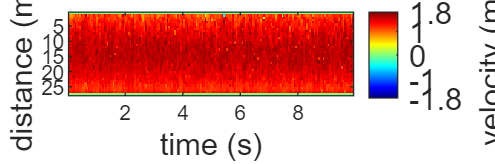


% create a time and distance vector for plot axis
time=(1:size(v,2))*res_temp_dual;
dist=(1:size(v,1))*1000*res_espac; 
tamFonte=12;
% plots spatiotemporal velocity map - with correction
imagesc(time,dist,v),c1=colorbar;
caxis([-vmax vmax]);colormap(jet);c1.Ticks=[-1.8 -1 0 1 1.8];
xlabel('time (s)', "FontSize", tamFonte);ylabel('distance (mm)', "FontSize", tamFonte); c1.Label.String = 'velocity (m/s)';c1.FontSize=tamFonte;



% plots spatiotemporal velocity map -no correction
disp('No outlier correction');

No outlier correction


figure('rend','painters','pos',[100 100 1200 400]);
mask1_outliersc=(vsc<acq.JL/2) & (vsc> 0.05);
outliers=sum(sum((vsc<0)|(vsc>2*acq.JL)|(mask1_outliersc)))

outliers = 193

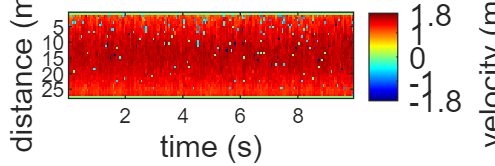


imagesc(time,dist,vsc),c1=colorbar;%
caxis([-vmax vmax]);colormap(jet);c1.Ticks=[-1.8 -1 0 1 1.8];
xlabel('time (s)', "FontSize", tamFonte);ylabel('distance (mm)', "FontSize", tamFonte); c1.Label.String = 'velocity (m/s)';c1.FontSize=tamFonte;

## Plot spatial velocity profile


figure('rend','painters','pos',[100 100 800 400]);hold all

spat_profile = mean(v,2); % with correction
spat_profile_sc=mean(vsc,2);%no correction
%ylim([0 1]);
%grid on


% generete theoretical velocity profile based in
% the power law model
rho = 1000; dia = 25.9e-3; visc = 8.9e-4; % Pa.s
Re = rho*dia*acq.JL/visc; n = -1.7 + 1.8*log10(Re);
f = (100*Re)^(-1/4);
rh = linspace(0,dia/2,size(v,1)/2+1);%
Umax = acq.JL*(1+1.33*sqrt(f)); % maximum flow velocity(theoretical)
vmet1 = Umax*(1-2.*rh./dia).^(1/n); % half profile
vmet2 = fliplr(vmet1);
spat_profile_theor = [vmet2(1:end-1) vmet1]; %full theoretical profile
clear vmet1;clear vmet2;clear rh; %flush temporary variables
%plot all profiles
r = linspace(0,26,length(spat_profile));
plot(r,spat_profile_sc,'-mo',"LineWidth",1);% no correction 
plot(r,spat_profile,'b*',"LineWidth",1);% with correction
plot(r,spat_profile_theor,'-k+',"LineWidth",1);%theorectical

%plots horizontal line to indicate the maximum conventonal velocity
% for each PRT
hor_limit=ones(1,length(spat_profile));%*va1/sind(acq.angulo);
plot(r,hor_limit*va1/sind(acq.angulo),'r--',"LineWidth",1);
plot(r,hor_limit*va2/sind(acq.angulo),'g--',"LineWidth",1);
axis ([0 26 0 acq.JL+0.5]);% adjust axis
ylabel('velocity (m/s)'); 
xlabel('distance (mm)');
axprof = gca;
hold off;

MeanVelocity=mean(mean(spat_profile))

MeanVelocity = 1.3503

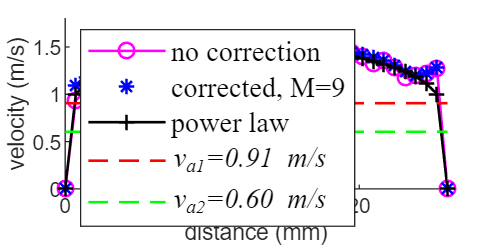


%display legende
lgd=legend('no correction',['corrected, M=' num2str(M) ],...
    'power law',...
    ['\it{v_{a1}=}' num2str(va1/sind(acq.angulo),'%.2f') ' m/s'],...
    ['\it{v_{a2}=}' num2str(va2/sind(acq.angulo),'%.2f') ' m/s'],...
    'location','SouthWest');
lgd.FontName='CambriaMath';
lgd.FontSize=11;


disp(['res_temp_DualPRT=' num2str(1000*res_temp_dual),' ms ']);

res_temp_DualPRT=53.2801 ms 


disp(['m/n='  num2str(acq.m) '/' num2str(acq.n) ', res_espac=' num2str(res_espac*1000) ' mm']);

m/n=2/3, res_espac=0.746 mm


## Save data

acq.Nc=Nc;
acq.Ns=Ns;
acq.va1=va1;
acq.va2=va2;
acq.r=r;
acq.spat_profile=spat_profile;
acq.spat_profile_sc=spat_profile_sc;
acq.posfiltersize=posfiltersize;
acq.time=time;
acq.cropini=crop_ini;
acq.cropfim=crop_end;
acq.Mf=Mf;
acq.p=p;
acq.ciclosmatched=ciclosmatched;
acq.dec=dec;
acq.T1=T1;
acq.T2=T2;
acq.res_espac=res_espac;
acq.M=M;
%uncomment below to save data!
% acq.data=0;
% save(strcat(path,['results_SLETTERS_JL_' ...
%     num2str(acq.JL) '_cycles_' num2str(acq.ciclos) '_m_' num2str(acq.m) '_M_' num2str(M) '.mat']),'acq')